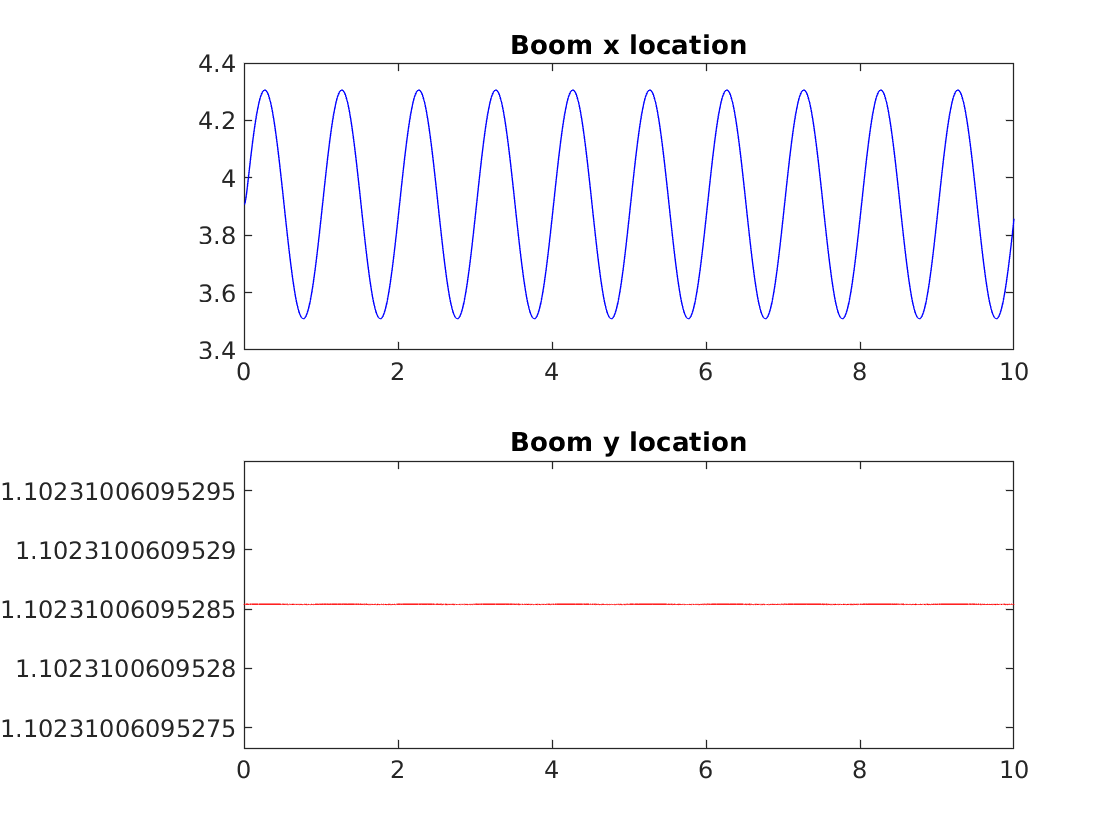

% Assuming your data is in a variable called 'val'
% 'val' is a 3D array with dimensions (M x N x P)

% Specify the color for the plot
line_color = [60 100 175] / 25;

% Define the time vector (assuming 'time' is available)
time = out.boom_x.time;
x_boom = out.boom_x.signals.values;
x_boom = squeeze(x_boom);

y_boom = out.boom_y.signals.values;
y_boom = squeeze(y_boom);

theta1 = out.theta1.Data;
theta1 = squeeze(theta1);

theta2 = out.theta2.Data;
theta2 = squeeze(theta2);

xt2 = out.xt2.Data;
%xt2 = squeeze(xt2);

% Iterate through each slice along the third dimension and plot it

subplot(2,1,1)
plot(time, x_boom, 'color', 'blue')
title("Boom x location")
subplot(2,1,2)
plot(time,y_boom, 'color', 'red')
title("Boom y location")% Create a figure

%Save data into csv file 
%time
%x_boom
%y_boom
fc1 = out.torques.fc1.Data;
fc2 = out.torques.fc2.Data;
fct2 = out.torques.fct2.Data;

all = [time, x_boom, y_boom, theta1, theta2, xt2, fc1, fc2, fct2]

all = 1.0e+05 *

         0    0.0000    0.0000         0         0    0.0000    0.6478    1.3818    0.0000
    0.0000    0.0000    0.0000         0         0    0.0000    0.6475    1.3812    0.0004
    0.0000    0.0000    0.0000         0         0    0.0000    0.6473    1.3807    0.0007
    0.0000    0.0000    0.0000         0         0    0.0000    0.6470    1.3801    0.0011
    0.0000    0.0000    0.0000         0         0    0.0000    0.6468    1.3795    0.0015
    0.0000    0.0000    0.0000         0         0    0.0000    0.6463    1.3784    0.0022
    0.0000    0.0000    0.0000         0         0    0.0000    0.6455    1.3767    0.0033
    0.0000    0.0000    0.0000         0         0    0.0000    0.6445    1.3744    0.0048
    0.0000    0.0000    0.0000         0         0    0.0000    0.6429    1.3706    0.0072
    0.0000    0.0000    0.0000         0         0    0.0000    0.6396    1.3632    0.0119


T = array2table(all);
T.Properties.VariableNames(1:9) = {'time', 'x_boom', 'y_boom', 'theta1', 'theta2', 'xt2', 'fc1', 'fc2', 'fct2'}

T = 10058×9 table
       time       x_boom    y_boom    theta1    theta2    xt2     fc1        fc2           fct2   
    __________    ______    ______    ______    ______    ___    _____    __________    __________

             0    3.9072    1.1023      0         0       0.5    64776    1.3818e+05    9.5757e-14
     2.543e-06    3.9072    1.1023      0         0       0.5    64751    1.3812e+05        36.853
    5.0859e-06    3.9072    1.1023      0         0       0.5    64726    1.3807e+05        73.688
    7.6289e-06    3.9072    1.1023      0         0       0.5    64701    1.3801e+05         110.5
    1.0172e-05    3.9072    1.1023      0         0       0.5    64676    1.3795e

writetable(T, 'training1.csv');
%writematrix(all, "training_1.csv")


